# Sample 5-3

## 周波数解析

2変量信号の周波数

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Fourier analysis

Frequency of bivariate signals

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 二変量余弦波の定義

(Definition of bivariate cosine wave)

        
$$\cos(\mathbf{\Omega}^T\mathbf{p})=\cos(\Omega_1 p_1 + \Omega_2 p_2)$$


ただし，(where)

        
$$\mathbf{\Omega} = \left(\begin{array}{c} \Omega_1 \\ \Omega_2 \end{array}\right)\in\mathbb{R}^2$$


        
$$\mathbf{p} = \left(\begin{array}{c} p_1 \\ p_2 \end{array}\right)\in\mathbb{R}^2$$


### 二変量角周波数の設定

(Bivariate angular frequency setting)

% Vertical angular frequency
f1 = 1;
Omega1 = 2*pi*f1;
% Horizontal angular frequnecy
f2 = 2;
Omega2 = 2*pi*f2;

% Definition of sampling points
[p1,p2] = meshgrid(-0.5:0.01:0.5,-0.5:0.01:0.5);

% Definition of a bivariate cosine wave
x = cos(Omega1*p1 + Omega2*p2);

### 二変量余弦波の表示

(Bivariate cosine wave display)

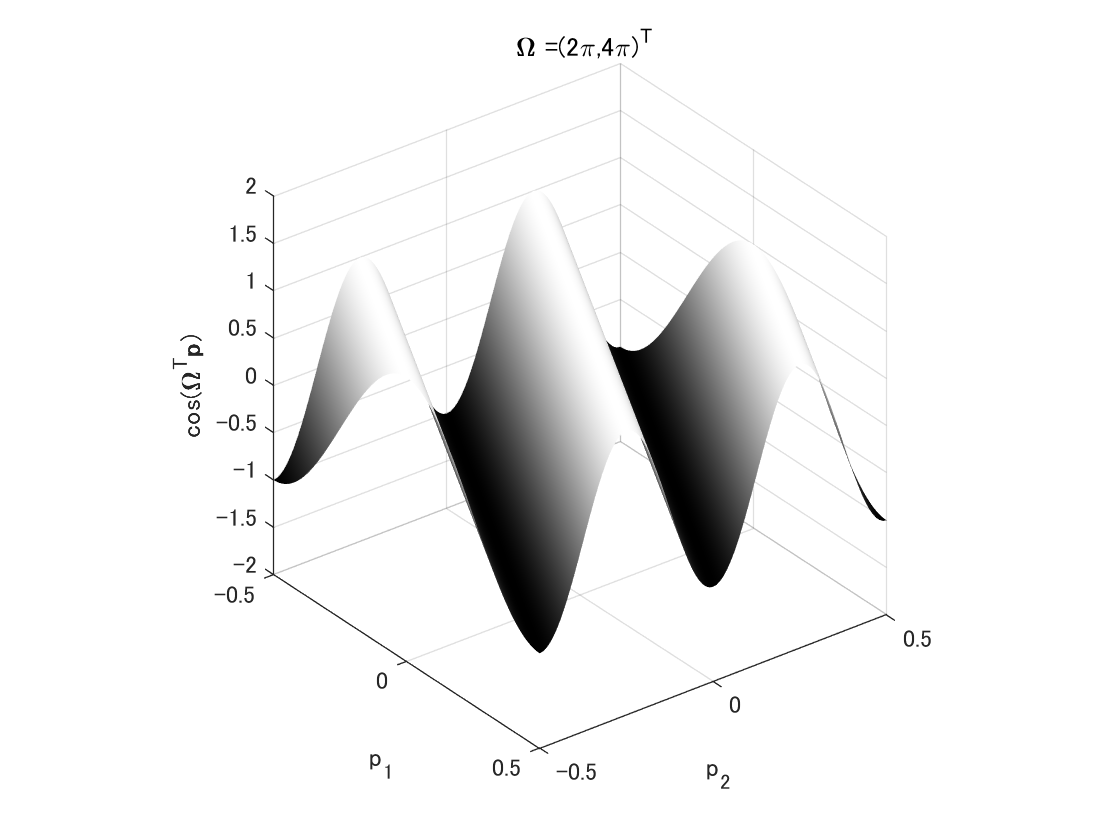

% Display of a bivariate cosine wave
surf(p2,p1,x)
xlabel('p_2')
ylabel('p_1')
zlabel('cos({\bf\Omega}^T{\bfp})')
title(['{\bf \Omega} =(' num2str(Omega1/pi) '\pi,' num2str(Omega2/pi) '\pi)^T'])
colormap gray
shading interp
axis([-0.5 0.5 -0.5 0.5 -2 2])
axis ij
axis vis3d

#### 表示を回転

(Rotate the display)

%{
stepAngle = 2;
for iAngle=1:stepAngle:360
    camorbit(0,stepAngle,'camera');
    drawnow
end
%}

© Copyright, Shogo MURAMATSU, All rights reserved.